## Setup the Virtual Simulation Environment

[**Instructions to setup RoboCup ARM provided virtual machine**](https://drive.google.com/file/d/1w9tBy3DKmZBKEfOqOFUXcT8hcQig6sNS/view)** (Appendix A)**

Follow the instructions above to setup the MathWorks provided Virtual Machine in your computer.

Find and open one of the environments for the RoboCup ARM Challenge. Note that there is more than on environment provided to ilustrate how objects in the environments are subject to changing positions and orientations based on the challenge instructions. 

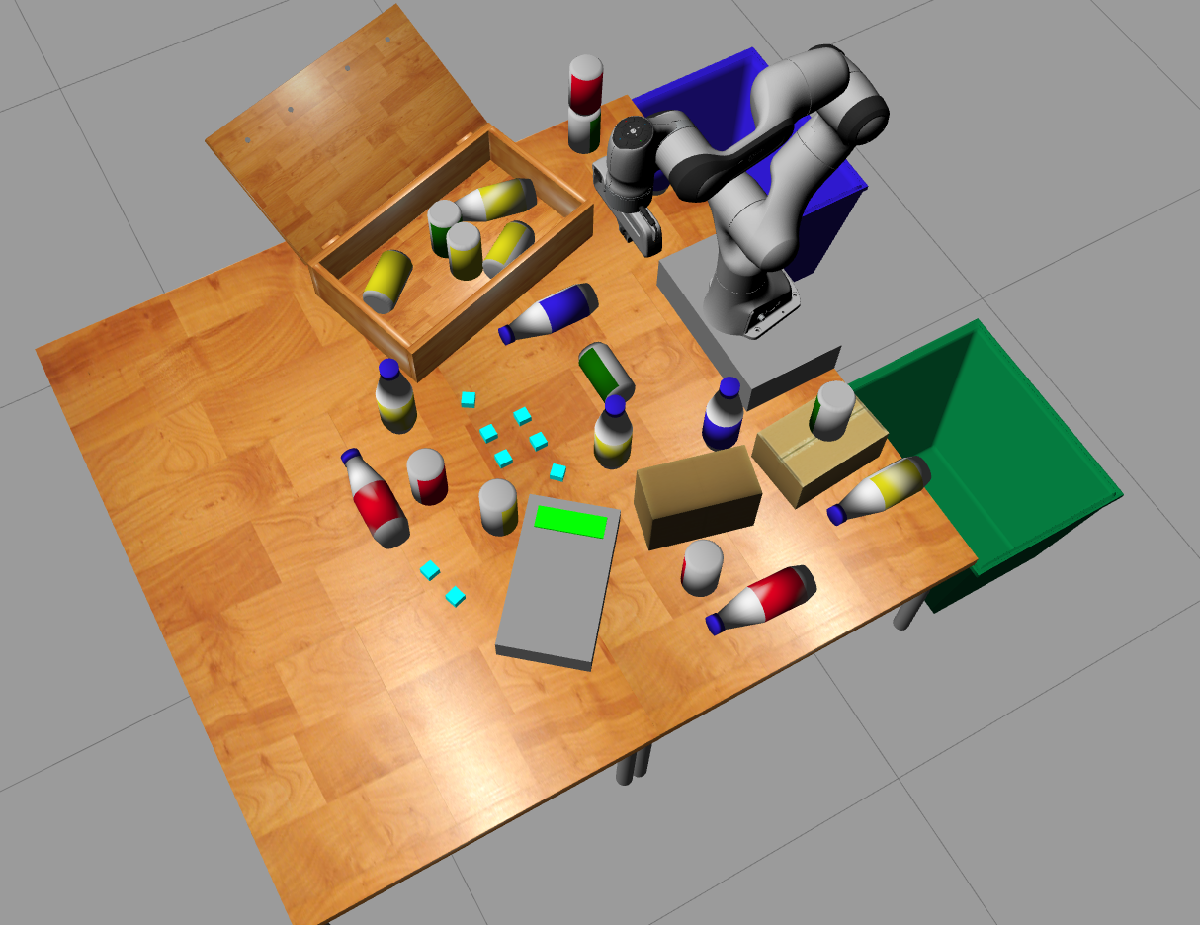

#### Connect MATLAB to Gazebo using the ROS Toolbox

Start a ROS node from MATLAB to interact with the Gazebo environment. For more information on interaction with the ROS ecosystem from MATLAB visit [Getting Started with ROS Toolbox](https://www.mathworks.com/help/ros/getting-started-with-ros-toolbox.html).

If you are having trouble with this step, or if you are waiting a long time for the nodes to communicate, try using the commented code in line 4. The IP address to be specified is the wireless network adapter address.

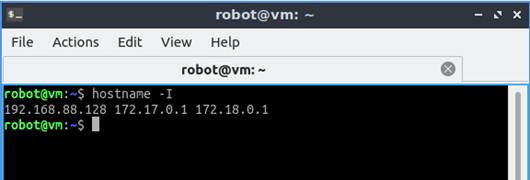

rosIP = "localhost"; % Change IP address!!    % IP address of ROS enabled machine  
rosshutdown; % shut down existing connection to ROS

Shutting down global node /matlab_global_node_52929 with NodeURI http://rdp-Altos-P10-F8:42021/ and MasterURI http://localhost:11311.


rosinit(rosIP,11311);

Initializing global node /matlab_global_node_44083 with NodeURI http://rdp-Altos-P10-F8:44233/ and MasterURI http://localhost:11311.


% rosinit(rosIP,'NodeHost','192.168.68.120') % Try specifying node host IP in case that there are multiple network adapters

## Initialize Robot and Start Simulator

#### Set initial robot configuration

setInitialConfig_franka; % DO NOT MODIFY

#### Unpause GAZEBO physics.

Unpausing the Gazebo simulation is necessary to make sure the environment physics are active.

physicsClient = rossvcclient('gazebo/unpause_physics'); %unpause physics
physicsResp = call(physicsClient,'Timeout',3); %send default message

## Control Gripper Using ROS Action Client

[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

gripperCommand.Command.Position = 4; %0 is fully closed, 4 is fully open
gripperCommand.Command.MaxEffort = 50; %N
gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
gripGoal.Command = gripperCommand.Command;
% waitForServer(gripAct); % Can use this function if concerned with missed
% goals but generally it should work correctly.
sendGoal(gripAct,gripGoal)
% gripper_pub=rospublisher("/franka_gripper/grasp/goal");
% gripper_mess=rosmessage("franka_gripper/GraspActionGoal")
% gripper_mess.goal.width=0.067
% gripper_mess.goal.epsilon.inner=0.01
% gripper_mess.goal.epsilon.outer=0.01
% gripper_mess.speed=0.1
% gripper_mess.force=20
% send(gripper_pub,gripper_mess);

## Control Gripper Position using ROS Action Client

#### Setup ROS message and publisher for Joint Control

jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");

#### Define Gripper Pose

This section defines the desired gripper location and orientation using a homogeneous transformation. [Learn more about homogeneous transform here.](https://www.mathworks.com/help/robotics/coordinate-system-transformations.html)

To reset pose to approximate initial configuration, set the gripper location to [0.35, 0.0001, 0.5] and orientation to [-pi. -0.01,0]

gripperX = 0.19;
gripperY = -0.04;
gripperZ = 0.99;
gripperTranslation = [gripperX gripperY gripperZ];
gripperRotationX = -pi; % radians
gripperRotationY = 0; % radians
gripperRotationZ = 0; % radians

jointMess.Pose.Position.X = gripperX;
jointMess.Pose.Position.Y = gripperY;
jointMess.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
jointMess.Pose.Orientation.W = quat(1);
jointMess.Pose.Orientation.X = quat(2);
jointMess.Pose.Orientation.Y = quat(3);
jointMess.Pose.Orientation.Z = quat(4);
send(jointPub,jointMess);

## **Effective use of RGB camera**

Data processed from the depth camera leads to successful classification of at least one bottle or can.

### Using a YoloV2 model pre-trained on two classes of objects (bottle, can)

disp('*-----Object Detection and Classification-----*')

*-----Object Detection and Classification-----*



% Getting Yolov2 model
% Load deep learning model for object detection
temp = load('exampleHelperYolo2DetectorROSGazebo.mat');
DetectorModel = temp.detectorYolo2;

% Detect parts
% This function detects parts using a pre-trained deep learning model.

% Read image from simulated Gazebo camera
rgbImg = getRGBImage

Getting RGB Image


rgbImg = 480×640×3 uint8 array
rgbImg(:,:,1) =

   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   1


% Detect parts and show labels
[bboxes,~,labels] = detect(DetectorModel,rgbImg);
if ~isempty(labels)
    labeledImg = insertObjectAnnotation(rgbImg,'Rectangle',bboxes,cellstr(labels));
    imshow(labeledImg);            
end

### Detect Objects Using Pretrained YOLO v2 Object Detector

name = "tiny-yolov2-coco";
% Create YOLO v2 object detector by using the pretrained YOLO v2 network.
detector = yolov2ObjectDetector(name);
% Display and inspect the properties of the YOLO v2 object detector.matlab:helpPopup yolov2ObjectDetector
disp(detector)

  yolov2ObjectDetector with properties:

            ModelName: 'tiny-yolov2-coco'
              Network: [1×1 DAGNetwork]
    TrainingImageSize: [416 416]
          AnchorBoxes: [5×2 double]
           ClassNames: [person    bicycle    car    motorbike    …    ]



% Read image from simulated Gazebo camera
img = getRGBImage

Getting RGB Image


img = 480×640×3 uint8 array
img(:,:,1) =

   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   155   1

% Detect objects in image by using the pretrained YOLO v2 object detector.
[bboxes,scores,labels] = detect(detector,img);
% Display the detection results.
detectedImg = insertObjectAnnotation(img,"Rectangle",bboxes,labels);
figure
imshow(detectedImg)

% use this to calculate and copy pase configurations
pose=getCurrentRobotJConfig;
disp(pose)

   -0.0056   -0.4511   -0.0530   -0.8173   -0.0638    0.9562    0.6829



## Pick-Place in Static Region

setInitialConfig_franka; % DO NOT MODIFY
jointMess = rosmessage("geometry_msgs/PoseStamped");
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
pause(2);
[gripAct,gripGoal] = rosactionclient('/franka_gripper/gripper_action');
gripperCommand = rosmessage(gripAct);

### Red Horizontal Bottle in Static Region

setInitialConfig_franka;
 
gripperGoal(4, gripAct, gripGoal, gripperCommand,20)
c_pose= [0.4; 0; 0.4];
g_pose= [0.31; 0.64; 0.1];
% 4747655.122846143, 9347.767000000];
% Interactive marker 'equilibrium_pose' contains unnormalized quaternions. This warning will only be output once but may be true for others; enable DEBUG messages for ros.rviz.quaternions to see more details.

smoothen_motion(c_pose,g_pose,0.1)
 
c_pose=[0.31; 0.64; 0.1];
g_pose=[0.32; 0.63; -0.077];
smoothen_motion(c_pose,g_pose,0.01)
gripperGoal(3.3, gripAct, gripGoal, gripperCommand,30)

c_pose=[0.32; 0.63; -0.077];
g_pose=[0.31; 0.64; 0.1];
smoothen_motion(c_pose,g_pose,0.02)
 
c_pose=[0.31; 0.64; 0.1];
g_pose=[0.31; 0; 0.4];
smoothen_motion(c_pose,g_pose,0.02)
 
 c_pose=[0.31; 0; 0.4];
 g_pose=[-0.4; -0.5; 0.4];
smoothen_motion(c_pose,g_pose,0.02)

gripperGoal(3.99, gripAct, gripGoal, gripperCommand,30)

### **Green Can in Static Region**

setInitialConfig_franka;
gripperGoal(0.1, gripAct, gripGoal, gripperCommand, 20);

c_pose = [0.4; 0.0; 0.4];
g_pose = [0.06; 0.36; 0.02];
smoothen_motion(c_pose, g_pose, 0.05);

c_pose = [0.06; 0.36; 0.02];
g_pose = [-0.2; 0.36; 0.02];
smoothen_motion(c_pose, g_pose, 0.1)

setInitialConfig_franka;
gripperGoal(0.1, gripAct, gripGoal, gripperCommand, 20);

### Red Can in Static Region 

setInitialConfig_franka;

gripperX = 0.4;
gripperY = 0.0;
gripperZ = 0.4;
gripperRotationX = -pi; % radians
gripperRotationY = 0; % radians
gripperRotationZ = -pi/2; % radians
jointMess.Pose.Position.X = gripperX;
jointMess.Pose.Position.Y = gripperY;
jointMess.Pose.Position.Z = gripperZ;
quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
jointMess.Pose.Orientation.W = quat(1);
jointMess.Pose.Orientation.X = quat(2);
jointMess.Pose.Orientation.Y = quat(3);
jointMess.Pose.Orientation.Z = quat(4);
send(jointPub,jointMess);

gripperGoal(0.1, gripAct, gripGoal, gripperCommand, 20);

gripperGoal(3.9, gripAct, gripGoal, gripperCommand, 20);

c_pose = [0.4; 0.0; 0.4];
g_pose = [0.4; 0.51; 0.03];
smoothen_motion(c_pose, g_pose, 0.05);

c_pose = [0.4; 0.51; 0.03];
g_pose = [0.4; 0.51; -0.025];
smoothen_motion(c_pose, g_pose, 0.05);

gripperGoal(3.3, gripAct, gripGoal, gripperCommand, 20);

c_pose = [0.4; 0.51; -0.025];
g_pose = [0.4; 0.51; 0.2];
smoothen_motion(c_pose, g_pose, 0.01);

c_pose = [0.4; 0.51; 0.2];
g_pose = [-0.3; 0.51; 0.2];
smoothen_motion(c_pose,g_pose,0.05);

gripperGoal(3.9, gripAct, gripGoal, gripperCommand, 20);

setInitialConfig_franka;

function smoothen_motion(c_pose, g_pose, speed)
jointPub = rospublisher("/cartesian_impedance_example_controller/equilibrium_pose");
jointMess = rosmessage("geometry_msgs/PoseStamped");
i_poses = c_pose;
f_poses = g_pose;
t = 0.5 + max(abs(i_poses - f_poses))/speed;
[Qi,T] = get_polynomial_trajectory(i_poses(1), f_poses(1), t, 0.05);
%jointMess.Pose.Position.Z = pz;
%send(jointPub,jointMess);
 Q = zeros(length(f_poses), length(T));
    Q(1,:) = Qi;
    for i=2:length(f_poses)
        [Qi,T] = get_polynomial_trajectory(i_poses(i), f_poses(i), t, 0.05);
        Q(i,:) = Qi;
    end
    Q = Q';
for j =1:length(Q)
  jointMess.Pose.Position.X = Q(j,1);
  jointMess.Pose.Position.Y = Q(j,2);
  jointMess.Pose.Position.Z = Q(j,3);
  send(jointPub,jointMess);
  pause(0.05)
end  

end

function goToGoal(poses, goalConfigStaticArray, jointPub, jointMess)
    % Iterate over the array of arrays
    for i = 1:numel(poses)
        gripperX = poses{i}(1);
        gripperY = poses{i}(2);
        gripperZ = poses{i}(3);
        gripperTranslation = [gripperX gripperY gripperZ];
        gripperRotationX = -pi; % radians
        gripperRotationY = -0.01; % radians
        gripperRotationZ = 0; % radians
        
        jointMess.Pose.Position.X = gripperX;
        jointMess.Pose.Position.Y = gripperY;
        jointMess.Pose.Position.Z = gripperZ;
        quat = angle2quat(gripperRotationX, gripperRotationY, gripperRotationZ, "XYZ");
        jointMess.Pose.Orientation.W = quat(1);
        jointMess.Pose.Orientation.X = quat(2);
        jointMess.Pose.Orientation.Y = quat(3);
        jointMess.Pose.Orientation.Z = quat(4);
        send(jointPub,jointMess);
    
        % Wait until the robot reaches destination
        pause(1.0);        % this pause is needed to start asking for movement status
        isAway = true;
        disp('Waiting until robot reaches the desired configuration');
        while isAway
            isAway = checkTargetAchieved(goalConfigStaticArray{i});
            pause(1);
       end
        fprintf('Goal %d Achieved',i);
    end
end
function gripperGoal(position, gripAct, gripGoal, gripperCommand, effort)
    gripperCommand.Command.Position = position; %0 is fully closed, 4 is fully open
    gripperCommand.Command.MaxEffort = effort; %N
    gripperCommand.Command.Position = gripperCommand.Command.Position / 100;
    gripGoal.Command = gripperCommand.Command;
    waitForServer(gripAct); % Can use this function if concerned with missed
    % goals but generally it should work correctly.
    sendGoal(gripAct,gripGoal)
    pause(5)
end

## **Function Definitions**

function JConfig = getCurrentRobotJConfig
    jMsg = receive(rossubscriber('/joint_states'));
    JConfig =  jMsg.Position(1:7)';
end

% Receive Camera Image Using ROS Subscriber
function rgbImg = getRGBImage
    disp("Getting RGB Image")
    rgbImgSub = rossubscriber("/camera/rgb/image_raw","sensor_msgs/Image","DataFormat","struct");
    curImage = receive(rgbImgSub,3);
    pause(1)
    rgbImg = rosReadImage(rgbImgSub.LatestMessage); 
end

% Receive Depth Image Using ROS Subscriber
function depthImg = getDepthImage
    disp("Getting Depth Image")
    rgbDptSub = rossubscriber('/camera/depth/image_raw');
    curDepth = receivesi(rgbDptSub,3ved       
    end           
end